% Load the FULL dataset
data = load('KmediodFULLcluster.mat');

% Extract centroids
C = data.kmFULL.C;

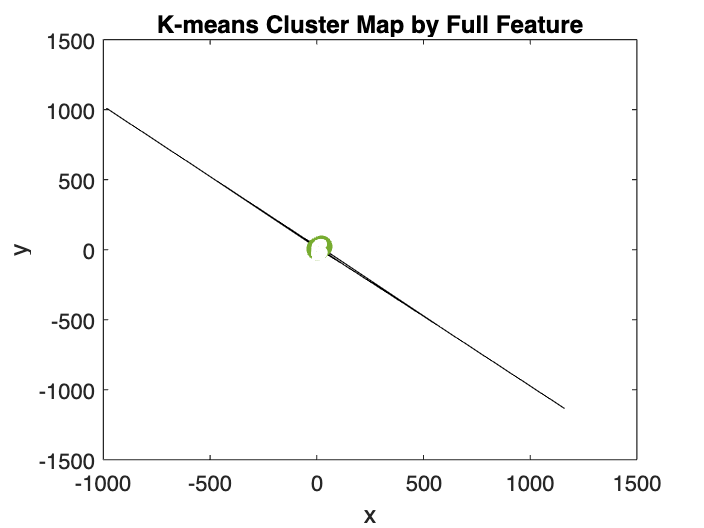


% Create a scatter plot of the centroids
figure;
[vx, vy] = voronoi(C(:,1), C(:,2)); % Assumes the centroids are in the first two columns
plot(vx, vy, 'k-'); % Draw Voronoi diagram in black
hold on;
scatter(C(:,1), C(:,2), 100, 'filled'); % Centroids in filled color
% Add labels for each cluster
for i = 1:size(C, 1)
    text(C(i, 1), C(i, 2), num2str(i), 'FontSize', 12, 'FontWeight', 'bold', 'HorizontalAlignment', 'center','Color', 'white');
end
title('K-means Cluster Map by Full Feature');
xlabel('x'); % 
ylabel('y');
hold off;

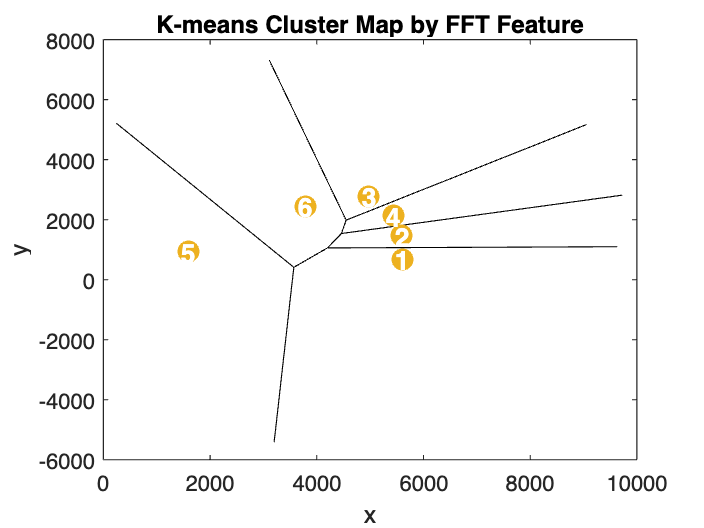


% Load the FFT dataset
data = load('KmediodFFTcluster.mat');

% Extract centroids
C = data.kmFFT.C;

% Create a scatter plot of the centroids
figure;
[vx, vy] = voronoi(C(:,1), C(:,2)); % Assumes the centroids are in the first two columns
plot(vx, vy, 'k-'); % Draw Voronoi diagram in black
hold on;
scatter(C(:,1), C(:,2), 100, 'filled'); % Centroids in filled color
% Add labels for each cluster
for i = 1:size(C, 1)
    text(C(i, 1), C(i, 2), num2str(i), 'FontSize', 12, 'FontWeight', 'bold', 'HorizontalAlignment', 'center','Color', 'white');
end
title('K-means Cluster Map by FFT Feature');
xlabel('x'); % 
ylabel('y');
hold off;

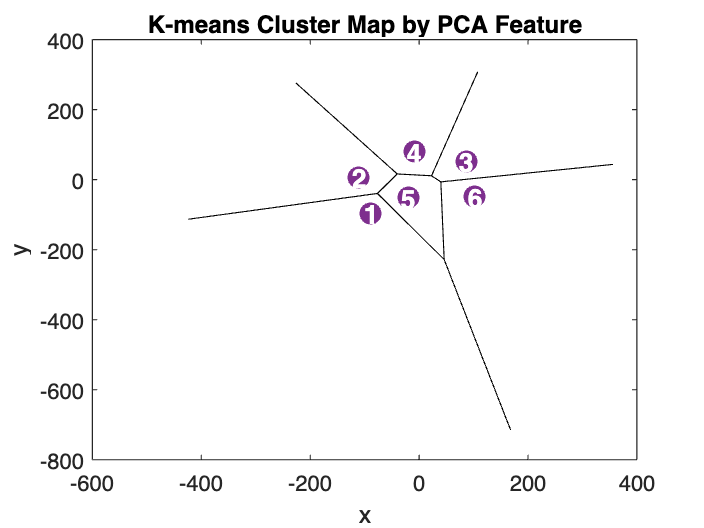


% Load the PCA dataset
data = load('KmediodPCAcluster.mat');

% Extract centroids
C = data.kmPCA.C;

% Create a scatter plot of the centroids
figure;
[vx, vy] = voronoi(C(:,1), C(:,2)); % Assumes the centroids are in the first two columns
plot(vx, vy, 'k-'); % Draw Voronoi diagram in black
hold on;
scatter(C(:,1), C(:,2), 100, 'filled'); % Centroids in filled color
% Add labels for each cluster
for i = 1:size(C, 1)
    text(C(i, 1), C(i, 2), num2str(i), 'FontSize', 12, 'FontWeight', 'bold', 'HorizontalAlignment', 'center','Color', 'white');
end
title('K-means Cluster Map by PCA Feature');
xlabel('x'); % 
ylabel('y');
hold off;

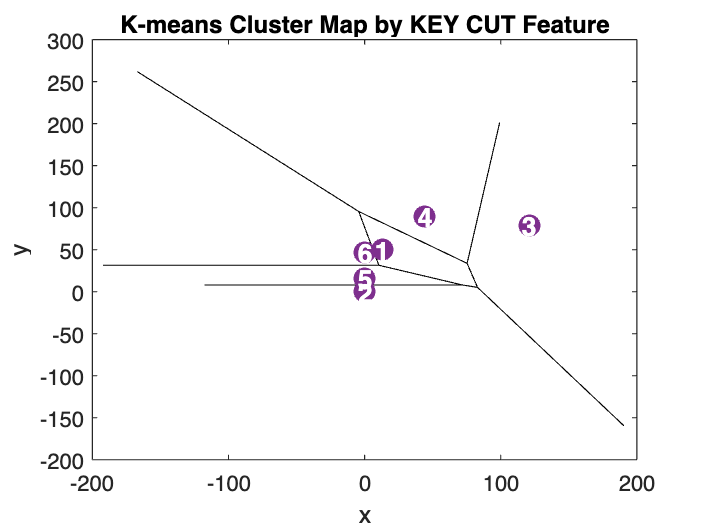


% Load the keyCut dataset
data = load('KmediodKEYcluster.mat');

% Extract centroids
C = data.kmKEY.C;

% Create a scatter plot of the centroids
figure;
[vx, vy] = voronoi(C(:,1), C(:,2)); % Assumes the centroids are in the first two columns
plot(vx, vy, 'k-'); % Draw Voronoi diagram in black
hold on;
scatter(C(:,1), C(:,2), 100, 'filled'); % Centroids in filled color
% Add labels for each cluster
for i = 1:size(C, 1)
    text(C(i, 1), C(i, 2), num2str(i), 'FontSize', 12, 'FontWeight', 'bold', 'HorizontalAlignment', 'center','Color', 'white');
end
title('K-means Cluster Map by KEY CUT Feature');
xlabel('x'); % 
ylabel('y');
hold off;

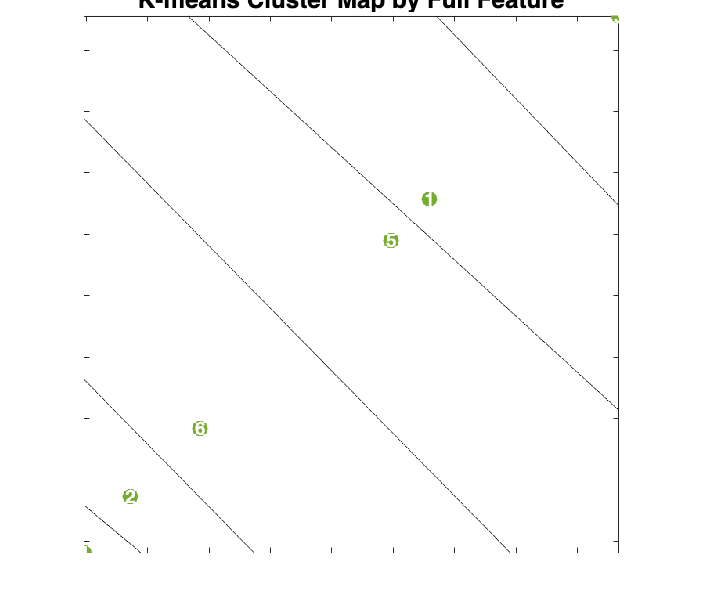

% Call the function for each dataset
createVoronoiImage('KmediodFULLcluster.mat', 'K-means Cluster Map by Full Feature');

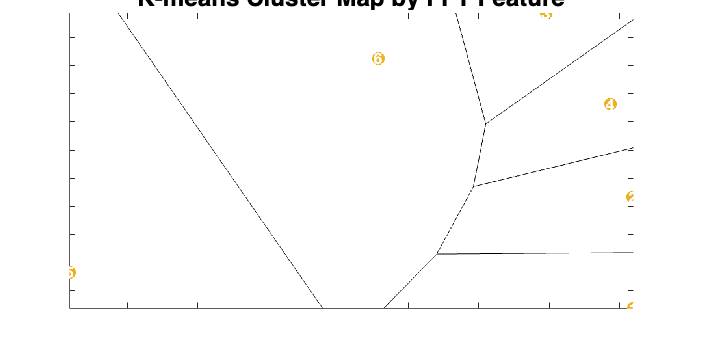

createVoronoiImage('KmediodFFTcluster.mat', 'K-means Cluster Map by FFT Feature');

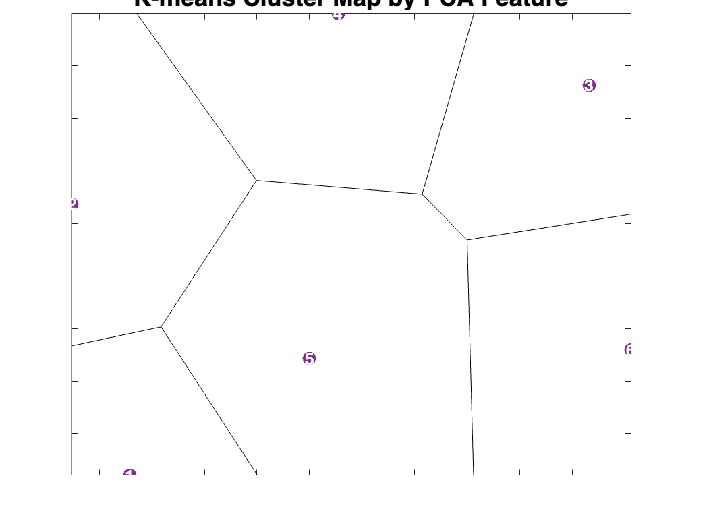

createVoronoiImage('KmediodPCAcluster.mat', 'K-means Cluster Map by PCA Feature');

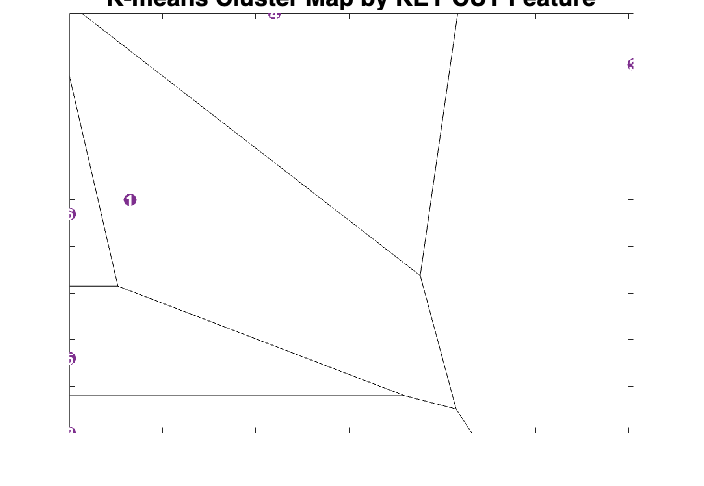

createVoronoiImage('KmediodKEYcluster.mat', 'K-means Cluster Map by KEY CUT Feature');

function createVoronoiImage(filename, titleText)
    % Load the dataset
    data = load(filename);

    % Determine the correct field name and extract centroids
    fieldNames = fieldnames(data);
    if isempty(fieldNames)
        error('No data found in file.');
    end
    fieldName = fieldNames{1}; % Assume the first field is the correct one
    if ~isfield(data.(fieldName), 'C')
        error('No centroid field (C) found in the data structure.');
    end
    C = data.(fieldName).C;

    % Generate Voronoi diagram on an off-screen figure
    figure('Visible', 'off');
    [vx, vy] = voronoi(C(:,1), C(:,2)); % Assumes the centroids are in the first two columns
    plot(vx, vy, 'k-'); % Draw Voronoi diagram in black
    hold on;
    scatter(C(:,1), C(:,2), 100, 'filled'); % Centroids in filled color
    % Add labels for each cluster
    for i = 1:size(C, 1)
        text(C(i, 1), C(i, 2), num2str(i), 'FontSize', 12, 'FontWeight', 'bold', 'HorizontalAlignment', 'center', 'Color', 'white');
    end
    title(titleText);
    xlabel('x');
    ylabel('y');
    hold off;
    axis equal;
    xlim([min(C(:,1)) max(C(:,1))]); % Set limits to include all points
    ylim([min(C(:,2)) max(C(:,2))]);

    % Capture the plot as an image
    frame = getframe(gca);
    im = frame2im(frame);
    close; % Close the off-screen figure

    % Display the image
    figure;
    imshow(im);
    title(titleText);
end


%%

